## Known Variables

% Link Lengths [mm]

l1 = 55.227; l4 = l1; % Active Links
l2 = 125; l3 = 50; % Passive Links
l5 = 187.5; % Ground Link

% Define End-Effector Position
x = 60.8;
y = 80;


## Singularities

% % S1: L1 and L2 are colinear, L3 and L4 are colinear, J1 = J2 and J3 = J4
% 
% alphaS1 = rad2deg(acos((l5/2)/(l1+l2)))
% betaS1 = 180 - alphaS1
% 
% %S2: L1 L2 are colinear, L3 L4 are colinear, J1 = J2 + 180
% 


## Solving for Joint Angles

c = sqrt(x^2+y^2); % Position magntiude from Motor A to End-Effector

e = sqrt((l5-x)^2+y^2); % Positional magnitude from End-Effector to Motor B

alpha1 = rad2deg(atan(y/x)); % Angle between the ground link and the straight line formed between Motor A and End-effector

alpha2 = rad2deg(acos((l2^2-c^2-l1^2) / (-2*l1*c))); % Angle between straight line formed between Motor A and End-effector and active link 1

alpha = alpha1 + alpha2

alpha = 155.6682


beta1 = rad2deg(atan(y/(l5-x))); % Angle between ground link and straight line formed between End-effector and Motor B

beta2 = rad2deg(acos((l2^2-l1^2-e^2) / (-2*l1*e))); % Angle between straight formed between End-effector and Motor B and active link 2

beta = 180 - (beta1 + beta2)

beta = 94.3741

## Plotting

clear plot

Link1 = line([0, l1*(cos(alpha*pi/180))], [0, l1*(sin(alpha*pi/180))])

Link1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 -50.3214]
              YData: [0 22.7547]
              ZData: [1×0 double]

  Show all properties


Link4 = line([l5,l5+l4*(cos(beta*pi/180))], [0, l4*(sin(beta*pi/180))])

Link4 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [187.5000 183.2880]
              YData: [0 55.0661]
              ZData: [1×0 double]

  Show all properties


Link2 = line([l1*(cos(alpha*pi/180)), x], [l1*(sin(alpha*pi/180)), y])

Link2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-50.3214 60.8000]
              YData: [22.7547 80]
              ZData: [1×0 double]

  Show all properties


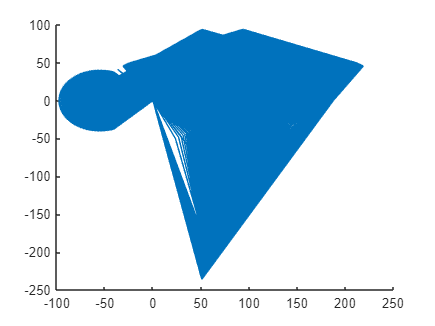

Link3 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [183.2880 60.8000]
              YData: [55.0661 80]
              ZData: [1×0 double]

  Show all properties


Link3 = line([l5+l4*(cos(beta*pi/180)), x], [l4*(sin(beta*pi/180)), y])


% Joint1 = viscircles([0, 0], 2)
% Joint1 = viscircles([l1*(cos(alpha*pi/180)), l1*(sin(alpha*pi/180))], 1)
% Joint3 = viscircles([x, y], 1)
% Joint4 = viscircles([l5+l4*(cos(beta*pi/180)), l1*(sin(beta*pi/180))], 1)
% Joint5 = viscircles([l5, 0], 2)


## Cycling Through Link Positions

y=95;
while true

    x = 93.75;
    y=y-5;
    [alpha, beta] = IK(l1,l2,l3,l4,l5,x,y);

    Link1 = line([0, l1*(cos(alpha*pi/180))], [0, l1*(sin(alpha*pi/180))])
    Link4 = line([l5,l5+l4*(cos(beta*pi/180))], [0, l4*(sin(beta*pi/180))])
    Link2 = line([l1*(cos(alpha*pi/180)), x], [l1*(sin(alpha*pi/180)), y])
    Link3 = line([l5+l4*(cos(beta*pi/180)), x], [l4*(sin(beta*pi/180)), y])

%     Joint1 = viscircles([0, 0], 2)
%     Joint1 = viscircles([l1*(cos(alpha*pi/180)), l1*(sin(alpha*pi/180))], 1)
%     Joint3 = viscircles([x, y], 1)
%     Joint4 = viscircles([l5+l4*(cos(beta*pi/180)), l1*(sin(beta*pi/180))], 1)
%     Joint5 = viscircles([l5, 0], 2)

    if(y == 65)

        break;

    end

end    
